clear
close all

## Set Parameters

n = 100;            % Number of Nodes
repititions = 2;    % Number of Repititions after S1

lrAlpha = 0.5;      % Learning Rate of S1
lrBeta = 0.2;       % Learning Rate of repititions after S1
bPercent = 0.7;     % Percent of Nodes that start as Blue Nodes
inverseTemp = 0.7;  % Inverse Temperature for SoftMax Function

## Random Network Creation

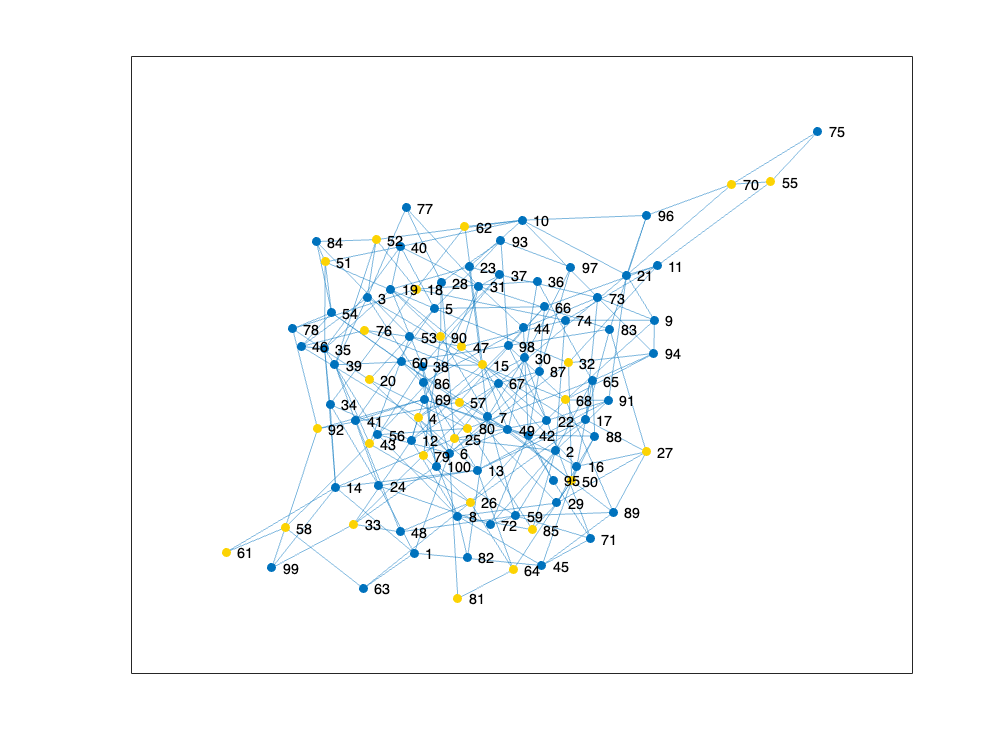

nodeConnect = zeros(n);

for i=1:n
    randomLength = randi([2, 7]);
    j = sum(sum(nodeConnect(i,:))+sum(nodeConnect(:,i)));
    while j <= randomLength
        j = sum(sum(nodeConnect(i,:))+sum(nodeConnect(:,i)));
        randomConnect = randi([1,n]);
        if randomConnect ~= i
            if nodeConnect(i,randomConnect) == 1 || sum(nodeConnect(randomConnect,:)) >= 7 || sum(nodeConnect(:,randomConnect)) >= 7
                continue
            else
                nodeConnect(i,randomConnect) = 1;
                nodeConnect(randomConnect, i) = 1;
            end
        end
    end
end

nodePredictions(1:n,1) = 0;
G = graph(nodeConnect);

for i=1:n 
    worldView = rand;
    nodePredictions(i,2) = degree(G,i);
    if worldView <= bPercent
        nodePredictions(i,1) = 1;
    end
end

h = plot(G);
yindicies = find(~nodePredictions);
bindicies = find(nodePredictions);

highlight(h,yindicies,'NodeColor','#fcd303');

## DeGroot

% Holds the values of every node through each stage
updateLog = nodePredictions(:,1);

% Needed for indexing updateLog
repititionsHold = repititions+2;

% Loop through all nodes
for i=1:n
    % find nodes connected to current node
    myFriends = find(nodeConnect(i,:));

    % Hold the value before it is updated as officially observed
    avgObservation = 0;
    % Loop through all connections
    for j=1:length(myFriends)
        % set aPE based on observation of Blue or Yellow
        aPE = 1;
        if (nodePredictions(myFriends(1,j),1)) ~= aPE
            aPE = -1;
        end
        % New Value = Current Value + alpha * (aPE - Current Valee) 
        avgObservation = avgObservation+nodePredictions(i,1)+(lrAlpha*(aPE-nodePredictions(i,1)));
        %% Softmax Function
        %nodePredictions(i,1) = 1/(1+exp(-inverseTemp*newValue));
    end
    % Average and record the observations of neighbors
    nodePredictions(i,1) = avgObservation/length(myFriends);
end

% Manually insert S1 into updateLog
updateLog(:,2) = nodePredictions(:,1);

% Repeat this loop until all repititions are completed
while repititions > 0
    % Set all current values to the stored values
    predictionsRound=nodePredictions;
    % loop through all nodes
    for i=1:n
        % Find connections to current nodes
        myFriends = find(nodeConnect(i,:));
        % Calculate the Total Local Degree
        totalConnections = sum(nodePredictions(myFriends,2));
        % Hold the value before it is updated as officially observed
        avgObservation = 0;
        % Loop through all connections
        for j=1:length(myFriends)
            % Stage s value = previous + beta * RD * aPE
            avgObservation=avgObservation+predictionsRound(i,1)+(lrBeta*(nodePredictions(myFriends(1,j),2)/totalConnections)*(nodePredictions(myFriends(1,j),1)-predictionsRound(i,1)));
        end
    end
    % Average all the observed values
    predictionsRound(i,1) = avgObservation/length(myFriends);
    % Decrement repititions
    repititions=repititions-1;
    % Index new stage into Update log 
    updateLog(:,repititionsHold-repititions) = predictionsRound(:,1);
    %% Softmax Function
    %updateLog(:,repititionsHold-repititions) = 1/(1+exp(-inverseTemp*predictionsRound(:,1)));    
    
    % Set current stage as previous stage for next repitition
    nodePredictions(:,1) = predictionsRound(:,1);
end

updateLog(:,end) = 1/(1+exp(-inverseTemp*updateLog(:,end)));

## RL

% % Holds the values of every node through each stage
% updateLog = nodePredictions(:,1);
% 
% % Needed for indexing updateLog
% repititionsHold = repititions+2;
% 
% % Loop through all nodes
% for i=1:n
%     % find nodes connected to current node
%     myFriends = find(nodeConnect(i,:));
%     % loop through all connections
%     for j=1:length(myFriends)
%         % set aPE based on observation of Blue or Yellow
%         aPE = 1;
%         if (nodePredictions(myFriends(1,j),1)) ~= aPE
%             aPE = -1;
%         end
%         % New Value = Current Value + alpha * (aPE - Current Valee) 
%         nodePredictions(i,1) = nodePredictions(i,1)+(lrAlpha*(aPE-nodePredictions(i,1)));
%         %% Softmax Function
%         %nodePredictions(i,1) = 1/(1+exp(-inverseTemp*newValue));
%     end
% end
% 
% % Manually insert S1 into updateLog
% updateLog(:,2) = nodePredictions(:,1);
% 
% % Repeat this loop until all repititions are completed
% while repititions > 0
%     % Set all current values to the stored values
%     predictionsRound=nodePredictions;
%     % loop through all nodes
%     for i=1:n
%         % Find connections to current nodes
%         myFriends = find(nodeConnect(i,:));
%         % Calculate the Total Local Degree
%         totalConnections = sum(nodePredictions(myFriends,2));
%         % Loop through all connections
%         for j=1:length(myFriends)
%             % Stage s value = previous + beta * RD * aPE
%             predictionsRound(i,1)=predictionsRound(i,1)+(lrBeta*(nodePredictions(myFriends(1,j),2)/totalConnections)*(nodePredictions(myFriends(1,j),1)-predictionsRound(i,1)));
%         end
%     end
%     % Decrement repititions
%     repititions=repititions-1;
%     % Index new stage into Update log 
%     updateLog(:,repititionsHold-repititions) = predictionsRound(:,1);
%     %% Softmax Function
%     %updateLog(:,repititionsHold-repititions) = 1/(1+exp(-inverseTemp*predictionsRound(:,1)));    
% 
%     % Set current stage as previous stage for next repitition
%     nodePredictions(:,1) = predictionsRound(:,1);
% end
% 
% 
% updateLog(:,end) = 1/(1+exp(-inverseTemp*updateLog(:,end)));